## csv全部点云根据真值配准


   for i=1:size(icpList,1)
        GrtM{i}=[icpList(i,1:4);icpList(i,5:8);icpList(i,9:12);icpList(i,13:16)];
   end

tar = 12

%    GrtM=GrtM';
   

## 真值误差

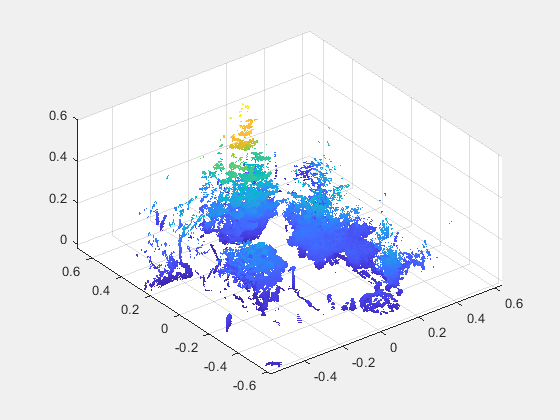

scannum=length(clouds);
for i=1:scannum
    Data_{i}=clouds{i}.Location;    

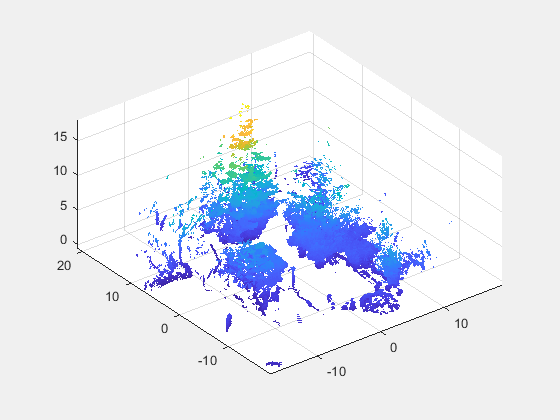

end
RotErr=0;
TranErr=0;
scannum=length(GrtR);
for i=1:scannum
    RotErr=norm((p(i).M(1:3,1:3)-GrtR{i}),'fro')+RotErr;
    TranErr=norm((p(i).M(1:3,4)-GrtT{i}),2)+TranErr;
end
RotErr=RotErr/scannum

TranErr=TranErr/scannum
 RotLogErr=log(RotErr)


clc;
close all;
clear;

## 读取展示单个

% datapath='./data/red_room/map2.ply';
% clouds=pcread(datapath);
% pcshow(clouds);


## 检测pointcloud分辨率(gridStep)

filepath='./data/global_frame_ap/';

RList = 180×1 cell 数组
    {3×3 double}
    {3×3 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 

prefix='PointCloud';
clouds=readCloudCsv(filepath,prefix,2,0,0);




## 展示配准


% s=30;

for i=1:length(clouds)
    curMotion=p(i).M;
    curMotion(1:3,4)=curMotion(1:3,4)./s;
    pcshow(pctransform( colorful_clouds{i},affine3d(curMotion')));
    hold on;
end



## 全部展示

for i=1:length(clouds)
%     curMotion=p(i).M;
%     curMotion(1:3,4)=curMotion(1:3,4)./s;
    pcshow(pcdenoise(clouds{i}));
end




%单配准展示

pcshow(fullTrimmedOutside);
hold on;
tar=12
currMotion=MotionGrt{tar};
currMotion(1:3,4)=MotionGrt{tar}(1:3,4)./s;
Tdata=currMotion*[clouds{tar}.Location';ones(1,size(clouds{tar}.Location,1))];
Tdata=Tdata';
pcshow(pointCloud(Tdata(:,1:3)));


model point Cloud转化

tar=12;
Modelpc=pointCloud(IcpModel(1:3,:)');
TData=(MotionGrt{tar}*IcpData);
Datapc=pointCloud(TData(1:3,:)');
pcshow(Modelpc);hold on;
pcshow(Datapc);

## 降噪

% for i=1:length(cloudsCopy)
% [clearClouds{i},inlinerOnes{i},outlierOnes{i}]=pcdenoise(cloudsCopy{i});
% end


## 展示噪声

% s=30;
% for i=1:length(cloudsCopy)
%     curMotion=p(i).M;
%     curMotion(1:3,4)=curMotion(1:3,4)./s;
%     pcshow(pctransform (pointCloud(cloudsCopy{i}.Location(outlierOnes{i},:)),affine3d(curMotion')));
%     hold on
% end



## read Motion from posescaner

% for i=1:size(posescannerleica,1)
%     MotionGrt{i}=[posescannerleica(i,1:4);posescannerleica(i,5:8);posescannerleica(i,9:12);posescannerleica(i,13:16)];
% end

